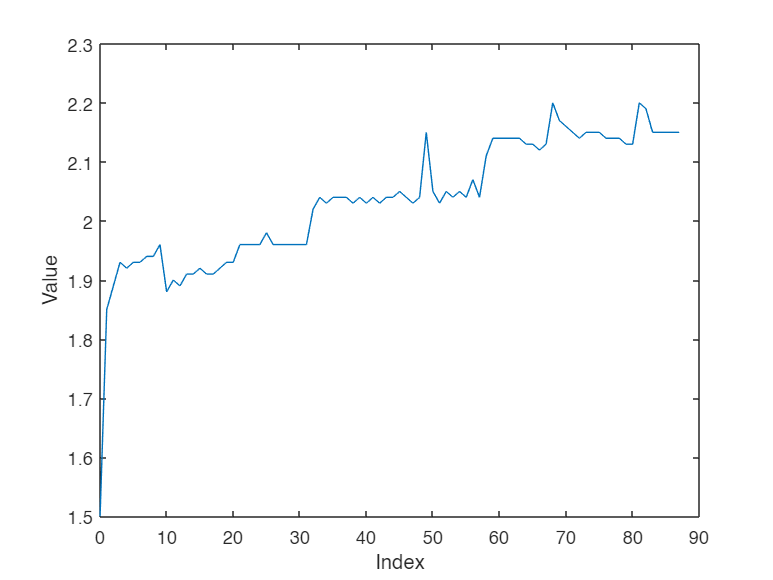

clc
clear all
close all
% Read data from the text file
% file = fopen("bm4.txt", 'r');
% data_out = textscan(file, '%f');
% fclose(file);
% data_out = data_out{1};

load("matlab.mat")

% Calculate time values
dt = 0.0062;  % Time step (in seconds)
t = (0:numel(data_out)-1) * dt;

% %Generate x-axis values (assuming equal spacing between data points)
x = 0:numel(data_out)-1;

% Plot the data
plot(x, data_out);
xlabel('Index');
ylabel('Value');

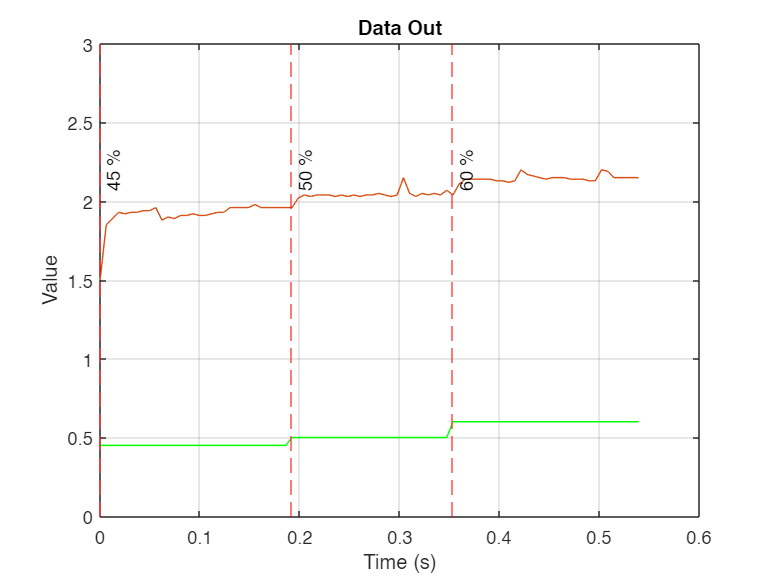


%Plot the data with respect to time
figure
% subplot(1,2,1)
data_in = [repmat(0.45, 1, 31), repmat(0.50, 1, 26), repmat(0.6, 1, 31)];
plot(t, data_in,'Color','green');
xlabel('Time (s)');
ylabel('Value');
title('Data In');
grid on;
hold on

%subplot(1,2,2)
plot(t, data_out);
hold on
xlabel('Time (s)');
ylim([0,3])
ylabel('Value');
title('Data Out');
grid on;

% Add vertical lines with text labels
hold on;
x_values = [0, 31*dt, 57*dt];  % Example x-values for the vertical lines
text_labels = {'45 %', '50 %', '60 %'};  % Example text labels
for i = 1:numel(x_values)
    xline(x_values(i), 'r--');  % Add vertical line at x-value
    text(x_values(i), max(data_out), text_labels{i}, 'VerticalAlignment', 'cap', 'HorizontalAlignment', 'center','Rotation', 90);
end
hold off;

### Create dataset for BM

data_out = reshape(data_out,length(data_out),1);
data_out = horzcat(data_out, t');
data_in = reshape(data_in,length(data_in),1);
data_in = horzcat(data_in, t');
